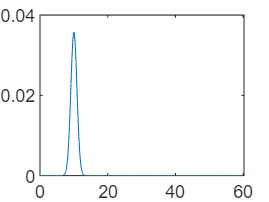

nPoint = 2^16;
z0 = 10;
sigma = 0:0.0083:(nPoint-1)*0.0083;
[fSigma,fSigma1,fSigma2,fSigma3,fSigma4,fSigma5,fSigma6,fSigma7,fSigma8] = fitfSigma(sigma);
pSigma = -4*pi*z0*sigma;
iSigma1 = fSigma1.*exp(1i*pSigma);
iSigma2 = fSigma2.*exp(1i*pSigma);
iSigma3 = fSigma3.*exp(1i*pSigma);
iSigma4 = fSigma4.*exp(1i*pSigma);
iSigma5 = fSigma5.*exp(1i*pSigma);
iSigma6 = fSigma6.*exp(1i*pSigma);
iSigma7 = fSigma7.*exp(1i*pSigma);
iSigma8 = fSigma8.*exp(1i*pSigma);
iSigma = fSigma.*exp(1i*pSigma);

[~,ifftIsigma11,intensity11,phase11]=ifftF(sigma,iSigma,nPoint);
[~,ifftIsigma1,intensity1,phase1]=ifftF(sigma,iSigma1,nPoint);
[~,ifftIsigma2,intensity2,phase2]=ifftF(sigma,iSigma2,nPoint);
[~,ifftIsigma3,intensity3,phase3]=ifftF(sigma,iSigma3,nPoint);
[~,ifftIsigma4,intensity4,phase4]=ifftF(sigma,iSigma4,nPoint);
[~,ifftIsigma5,intensity5,phase5]=ifftF(sigma,iSigma5,nPoint);
[~,ifftIsigma6,intensity6,phase6]=ifftF(sigma,iSigma6,nPoint);
[~,ifftIsigma7,intensity7,phase7]=ifftF(sigma,iSigma7,nPoint);
[zData,ifftIsigma8,intensity8,phase8]=ifftF(sigma,iSigma8,nPoint);
% deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
% deltaZ = 1/(2*nPoint*deltaSigma);
% zData = (1:nPoint)*deltaZ;
% ifftIsigma = ifft(iSigma);
% intensity = abs(ifftIsigma);
% phase0 = angle(ifftIsigma);

plot(zData,intensity1);

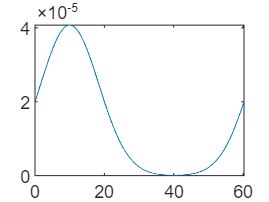

plot(zData,intensity2);

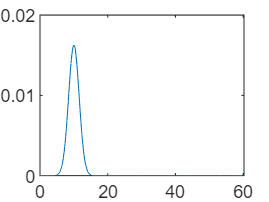

plot(zData,intensity3);

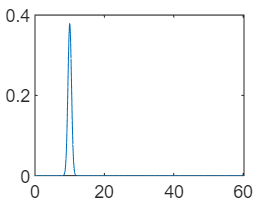

plot(zData,intensity4);

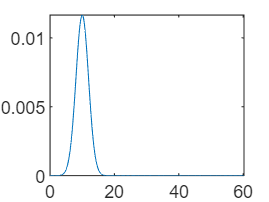

plot(zData,intensity5);

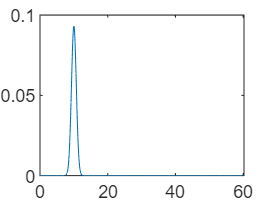

plot(zData,intensity6);

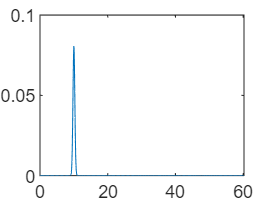

plot(zData,intensity7);

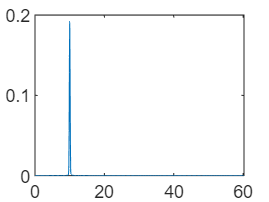

plot(zData,intensity8);

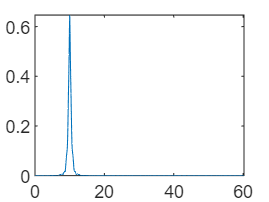


ifftIsigma = ifftIsigma1+ifftIsigma2+ifftIsigma3+ifftIsigma4+ifftIsigma5+ifftIsigma6+ifftIsigma7+ifftIsigma8;
plot(zData,abs(ifftIsigma));

function [fSigma,fSigma1,fSigma2,fSigma3,fSigma4,fSigma5,fSigma6,fSigma7,fSigma8] = fitfSigma(x)
%Coefficients (with 95% confidence bounds):
       a1 =       88.19  ;%(51.68, 124.7)
       b1 =       1.378  ;%(1.347, 1.409)
       c1 =      0.1243  ;%(0.0879, 0.1606)
       a2 =      0.9322  ;%(-1.209, 3.073)
       b2 =       1.542  ;%(1.518, 1.565)
       c2 =     0.01341  ;%(-0.02512, 0.05195)
       a3 =       69.18  ;%(-6.223, 144.6)
       b3 =        1.27  ;%(1.228, 1.312)
       c3 =     0.07202  ;%(0.03205, 0.112)
       a4 =       528.7  ;%(493.5, 563.8)
       b4 =       1.488  ;%(1.483, 1.494)
       c4 =      0.2199  ;%(0.2153, 0.2245)
       a5 =       62.39  ;%(-14.96, 139.7)
       b5 =       1.207  ;%(1.188, 1.225)
       c5 =     0.05735  ;%(0.04772, 0.06698)
       a6 =         181  ;%(163.3, 198.6)
       b6 =        1.87  ;%(1.867, 1.873)
       c6 =       0.158  ;%(0.153, 0.1629)
       a7 =      -60.41  ;%(-80.21, -40.6)
       b7 =        1.92  ;%(1.789, 2.051)
       c7 =      0.4102  ;%(0.3363, 0.4841)
       a8 =       57.07  ;%(54.59, 59.55)
       b8 =       1.735  ;%(1.728, 1.742)
       c8 =       1.039  ;%(1.023, 1.054)
     fSigma = a1*exp(-((x-b1)/c1).^2) + a2*exp(-((x-b2)/c2).^2) +... 
              a3*exp(-((x-b3)/c3).^2) + a4*exp(-((x-b4)/c4).^2) + ...
              a5*exp(-((x-b5)/c5).^2) + a6*exp(-((x-b6)/c6).^2) + ...
              a7*exp(-((x-b7)/c7).^2) + a8*exp(-((x-b8)/c8).^2);
     fSigma1 = a1*exp(-((x-b1)/c1).^2);
     fSigma2 = a2*exp(-((x-b2)/c2).^2);
     fSigma3 = a3*exp(-((x-b3)/c3).^2);
     fSigma4 = a4*exp(-((x-b4)/c4).^2);
     fSigma5 = a5*exp(-((x-b5)/c5).^2);
     fSigma6 = a6*exp(-((x-b6)/c6).^2);
     fSigma7 = a7*exp(-((x-b7)/c7).^2);
     fSigma8 = a8*exp(-((x-b8)/c8).^2);
end
function [zData,ifftIsigma,intensity,phase0]=ifftF(sigma,iSigma,nPoint)
deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase0 = angle(ifftIsigma);
end